# ISAC topology framework 

# Select topology BEFORE running for reproducibility.

cfg.topology = "bistatic"; % "monostatic" | "bistatic"
cfg.showResourceGrid = true;
cfg.printSensingLimits = true;

rng('default');                                            % Set the random number generator for reproducibility
carrierFrequency = 30e9;                                   % Carrier frequency (Hz)
wavelength = freq2wavelen(carrierFrequency);

Transmitter and receiver location.

txPosition = [0; 0; 0];                                    % Base station location

% Topology-dependent geometry
switch cfg.topology
    case "bistatic"
        rxPosition = [50; 60; 0];                          % User equipment location
    case "monostatic"
        rxPosition = txPosition;                           % Co-located Tx/Rx
    otherwise
        error('cfg.topology must be "monostatic" or "bistatic".');
end

Creation of transmitter and reciever 

txPower = 46;                                              % dBm
transmitter = phased.Transmitter('PeakPower', db2pow(txPower-30), 'Gain', 0);

numTxAntennas = 8;                                         % Number of antenna elements at the Tx array
element = phased.IsotropicAntennaElement('BackBaffled', true);
txArray = phased.ULA(numTxAntennas, wavelength/2, 'Element', element);
txOrientationAxes = eye(3);                                % Tx array orientation

receiver = phased.Receiver('AddInputNoise', true, 'Gain', 0, 'NoiseMethod', 'Noise figure',...
    'NoiseFigure', 5, 'ReferenceTemperature', 290);

% Topology-dependent Rx array and orientation
switch cfg.topology
    case "bistatic"
        numRxAntennas = 8;
        rxArray = phased.ULA(numRxAntennas, wavelength/2, 'Element', element);
        rxOrientationAxes = rotz(-90);
    case "monostatic"
        numRxAntennas = numTxAntennas;
        rxArray = txArray;
        rxOrientationAxes = txOrientationAxes;
end

Scatterers 

regionOfInterest = [0 120; -80 80];
numScatterers = 40;
[scatterers.Positions, scatterers.ReflectionCoefficients] = helperGenerateStaticScatterers(numScatterers, regionOfInterest);
scatterers.Velocities = zeros(size(scatterers.Positions));

targets.Trajectories = helperGetTargetTrajectories();
numTargets = numel(targets.Trajectories);
targets.ReflectionCoefficients = exp(1i*(2*pi*rand(1, numTargets)));

Channel

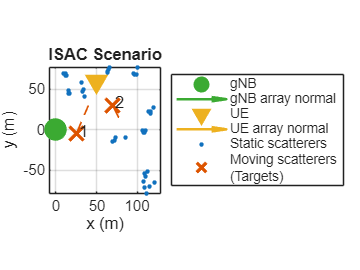

% Topology-dependent direct path
simulateDirectPath = cfg.topology == "bistatic";
channel = phased.ScatteringMIMOChannel('CarrierFrequency', carrierFrequency, 'TransmitArray', txArray,...
    'TransmitArrayPosition', txPosition, 'ReceiveArray', rxArray, 'ReceiveArrayPosition', rxPosition,...
    "TransmitArrayOrientationAxes", txOrientationAxes, "ReceiveArrayOrientationAxes", rxOrientationAxes,...
    'SimulateDirectPath', simulateDirectPath, 'ScattererSpecificationSource', 'Input Port', ...
    'ChannelResponseOutputPort',true,'Polarization','None');

helperVisualizeScatteringMIMOChannel(channel, scatterers.Positions, targets.Trajectories);
title('ISAC Scenario');

**5G Waveform Configuration**

channelBandwidth = 50;
bandwidthOccupancy = 0.9;
subcarrierSpacing = 60;

waveformConfig = helperGet5GWaveformConfiguration(channelBandwidth, bandwidthOccupancy, subcarrierSpacing);
waveformInfo = nrOFDMInfo(waveformConfig.Carrier);
transmissionBandwidth = subcarrierSpacing*1e3*waveformConfig.Carrier.NSizeGrid*12;
if cfg.printSensingLimits
    fprintf("Transmission bandwidth: %.2f MHz\n",transmissionBandwidth*1e-6);
end

Transmission bandwidth: 44.64 MHz



channel.SampleRate = waveformInfo.SampleRate;

**DM-RS parameters.**

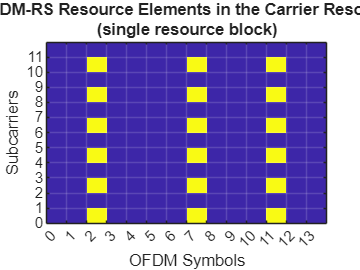

waveformConfig.PDSCH.DMRS.DMRSTypeAPosition = 2;
waveformConfig.PDSCH.DMRS.DMRSLength = 1;
waveformConfig.PDSCH.DMRS.DMRSAdditionalPosition = 2;
waveformConfig.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;
waveformConfig.PDSCH.DMRS.DMRSConfigurationType = 1;
if cfg.showResourceGrid
    resourceGrid = nrResourceGrid(waveformConfig.Carrier, waveformConfig.PDSCH.NumLayers);
    ind = nrPDSCHDMRSIndices(waveformConfig.Carrier, waveformConfig.PDSCH);
    resourceGrid(ind) = nrPDSCHDMRS(waveformConfig.Carrier, waveformConfig.PDSCH);
    helperVisualizeResourceGrid(abs(resourceGrid(1:12,1:14,1)));
    title({'PDSCH DM-RS Resource Elements in the Carrier Resource Grid', '(single resource block)'});
end

Doppler

% Literal computations from original scripts
[~,pdschInfo] = nrPDSCHIndices(waveformConfig.Carrier,waveformConfig.PDSCH);
Mt = max(diff(pdschInfo.DMRSSymbolSet));
ofdmSymbolDuration = max(waveformInfo.SymbolLengths)/waveformInfo.SampleRate;
maxDoppler = 1/(2*Mt*ofdmSymbolDuration);

Velocity

maxVelocity = dop2speed(maxDoppler, wavelength);
if cfg.topology == "monostatic"
    maxVelocity = maxVelocity/2;
end

Delay

Mf = min(diff(waveformConfig.PDSCH.DMRS.DMRSSubcarrierLocations));
maxDelay = 1/(2*Mf*subcarrierSpacing*1e3);
channel.MaximumDelaySource = 'Property';
channel.MaximumDelay = maxDelay;

Range 

propagationSpeed = physconst("LightSpeed");
if cfg.topology == "bistatic"
    baseline = vecnorm(txPosition-rxPosition);
    maxRange = maxDelay*propagationSpeed-baseline;
else
    baseline = 0;
    maxRange = maxDelay*propagationSpeed/2;
end
rangeResolution = propagationSpeed/transmissionBandwidth;
if cfg.printSensingLimits
    fprintf('Maximum unambiguous Doppler shift: %.2f kHz\n', maxDoppler*1e-3);
    fprintf('Maximum unambiguous velocity: %.2f m/s\n', maxVelocity);
    fprintf('Maximum time delay: %.2fe-6 s\n', maxDelay*1e6);
    fprintf('Maximum unambiguous %s range: %.2f m\n', cfg.topology, maxRange);
    fprintf('Range resolution: %.2f m\n', rangeResolution);
end

Maximum unambiguous Doppler shift: 5.45 kHz


Maximum unambiguous velocity: 54.43 m/s


Maximum time delay: 4.17e-6 s


Maximum unambiguous bistatic range: 1171.03 m


Range resolution: 6.72 m


**Channel Simulation and Sensing Data Processing**

numSensingFrames = 10;
dt = 0.4;
t = (0:numSensingFrames-1)*dt;

numAoA = ceil(2*pi*numRxAntennas);
aoaGrid = linspace(-90, 90, numAoA);
rxSteeringVector = phased.SteeringVector(SensorArray=channel.ReceiveArray);
rxsv = rxSteeringVector(carrierFrequency, aoaGrid);

numAoD = ceil(2*pi*numTxAntennas);
aodGrid = linspace(-90, 90, numAoD);
txSteeringVector = phased.SteeringVector(SensorArray=channel.TransmitArray);
txsv = txSteeringVector(carrierFrequency, aodGrid);
% Topology-dependen
if cfg.topology == "bistatic"
    rangeGrid = -20:rangeResolution/4:100;
    rangeFFTBins = (rangeGrid + baseline)/rangeResolution;
else
    rangeGrid = 0:rangeResolution/4:100;
    rangeFFTBins = (2*rangeGrid)/rangeResolution;
end
numRange = numel(rangeGrid);
numSubcarriers = waveformConfig.Carrier.NSizeGrid*12;
k = (0:numSubcarriers-1).';
rngsv = (exp(2*pi*1i*k*rangeFFTBins/numSubcarriers)/numSubcarriers);

2-D CFAR detector

numGuardCellsRange = ceil(rangeResolution/(rangeGrid(2)-rangeGrid(1))) + 1;
aoaResolution = ap2beamwidth((numRxAntennas-1)*channel.ReceiveArray.ElementSpacing, wavelength);
numGuardCellsAoA = ceil(aoaResolution/(aoaGrid(2)-aoaGrid(1))) + 1;
cfar2D = phased.CFARDetector2D('GuardBandSize',[numGuardCellsRange numGuardCellsAoA], 'TrainingBandSize', [4 6],...
    'ProbabilityFalseAlarm', 1e-5, 'OutputFormat', 'CUT result', 'ThresholdOutputPort', false);
offsetIdxs = cfar2D.TrainingBandSize + cfar2D.GuardBandSize;
rangeIdxs = offsetIdxs(1)+1:numel(rangeGrid)-offsetIdxs(1);
angleIdxs = offsetIdxs(2)+1:numel(aoaGrid)-offsetIdxs(2);
[sumRangeIdxs, aoaIdxs] = meshgrid(rangeIdxs, angleIdxs);
cutidx = [sumRangeIdxs(:).'; aoaIdxs(:).'];

clusterer = clusterDBSCAN();

Tracker

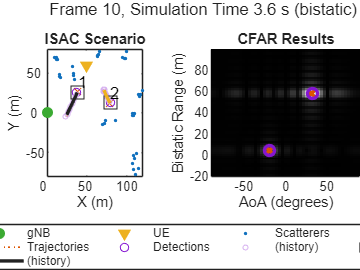


Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000

Throughput(Mbps) for 1 frame(s) = 1.7928
Throughput(%) for 1 frame(s) = 100.0000


tracker = helperConfigureTrackerByTopology(cfg.topology, txPosition, rxPosition, txOrientationAxes, rxOrientationAxes, rangeResolution, aoaResolution);
targetStateEstimates = zeros(4, numSensingFrames, 10);
trackIDs = [];

generateVisualizations = true;
if generateVisualizations
    scenarioCFARResultsFigure = figure;
    tl = tiledlayout(scenarioCFARResultsFigure, 1, 2, 'Padding', 'tight', 'TileSpacing', 'tight');
    scenarioPlotter = helperTheaterPlotter(tl);
    scenarioPlotter.plotTxAndRx(txPosition, rxPosition);
    scenarioPlotter.plotTrajectories(targets.Trajectories, t);
    scenarioPlotter.plotScatterers(scatterers.Positions);
    title(scenarioPlotter, 'ISAC Scenario');
    cfarResultsVisualizer = helperCFARResultsVisualizer(tl);
    xlabel(cfarResultsVisualizer, 'AoA (degrees)');
    if cfg.topology == "bistatic"
        ylabel(cfarResultsVisualizer, 'Bistatic Range (m)');
    else
        ylabel(cfarResultsVisualizer, 'Monostatic Range (m)');
    end
    title(cfarResultsVisualizer, 'CFAR Results');
end

numSymbolsPerFrame = waveformInfo.SlotsPerFrame*waveformInfo.SymbolsPerSlot;
%borrar si funciona sin esto 
%numDetectionsPerFrame = zeros(numSensingFrames,1);
%numTracksPerFrame = zeros(numSensingFrames,1);

for i = 1:numSensingFrames
    sensingCSI = helperSimulateLinkSingleFrame(transmitter, receiver, channel, waveformConfig, scatterers, targets, t(i));
    reset(channel);


    X = fft(sensingCSI, [], 2);
    X(:, 1, :, :) = 0;
    x = ifft(X, [], 2);

    x = permute(x, [4 1 3 2]);
    x = txsv'*reshape(x, numTxAntennas, []);

    x = permute(reshape(x, numAoA, numSubcarriers, numRxAntennas, numSymbolsPerFrame), [2 3 1 4]);
    x = rngsv.'*reshape(x, numSubcarriers, []);
    x = permute(reshape(x, numRange, numRxAntennas, numAoD, numSymbolsPerFrame), [2 1 3 4]);
    x = rxsv'*reshape(x, numRxAntennas, []);
    x = reshape(x, numAoA, numRange, []);
    sumRangeAoAMap = sqrt(sum(abs(x).^2, 3)).';

    cutResult = cfar2D(sumRangeAoAMap, cutidx);
    detectionIdxs = cutidx(:, cutResult);
    detectionValues = [rangeGrid(detectionIdxs(1,:)); aoaGrid(detectionIdxs(2,:))];

    [~, clusterids] = clusterer(detectionValues.');
    uniqClusterIds = unique(clusterids);
    m = numel(uniqClusterIds);
    clusteredDetections = zeros(2, m);

    for j = 1:m
        idxs = clusterids == uniqClusterIds(j);
        d = detectionValues(:, idxs);
        clusteredDetections(:, j) = mean(d, 2);
    end

    detections = helperFormatDetectionsForTrackerByTopology(cfg.topology, clusteredDetections, t(i), rangeResolution, aoaResolution);
    tracks = tracker(detections);

    for it = 1:numel(tracks)
        id = tracks(it).TrackID;
        trackIDs = union(trackIDs, id);
        targetStateEstimates(:, i, id) = tracks(it).State;
    end
    %borrar
    %numDetectionsPerFrame(i) = size(clusteredDetections,2);
    %numTracksPerFrame(i) = numel(tracks);

    

    if generateVisualizations
        targetPositions = zeros(numTargets, 3);
        for it = 1:numTargets
            targetPositions(it, :) = lookupPose(targets.Trajectories{it}, t(i));
        end
        scenarioPlotter.plotTargetPositions(targetPositions);

        if cfg.topology == "bistatic"
            measuredPositions = helperGetCartesianMeasurement(clusteredDetections, txPosition, rxPosition, rxOrientationAxes);
        else
            measuredPositions = helperGetMonostaticCartesianMeasurement(clusteredDetections, rxPosition, rxOrientationAxes);
        end
        scenarioPlotter.plotDetections(measuredPositions);
        scenarioPlotter.plotTracks(tracks);
% Visualize CFAR results 
        [trueRrx, trueAoA] = rangeangle(targetPositions.', rxPosition, rxOrientationAxes);
        [trueRtx, trueAoD] = rangeangle(targetPositions.', txPosition, txOrientationAxes);
      
        if cfg.topology == "bistatic"
            trueRange = trueRrx + trueRtx - baseline;
        else
            trueRange = trueRrx;
        end

        cfarResultsVisualizer.plotCFARImage(aoaGrid, rangeGrid, sumRangeAoAMap);
        cfarResultsVisualizer.plotTruth([trueRange; trueAoA(1, :)]);
        cfarResultsVisualizer.plotClusteredDetections(clusteredDetections);
        sgtitle(scenarioCFARResultsFigure, sprintf('Frame %d, Simulation Time %.1f s (%s)', i, t(i), cfg.topology), 'FontSize', 10);
        drawnow;
        
    end
end

Function of targets speed and heading

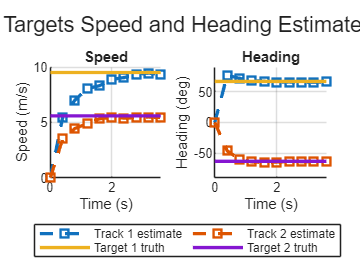

%% ISAC Scenario and CFAR Frame-by-Frame Visualization
%% Target Speed and Heading Estimation
helperPlotSpeedEstimationResults(t, targets.Trajectories, targetStateEstimates, trackIDs);

%borrar
%results.topology = cfg.topology;
%results.numDetectionsPerFrame = numDetectionsPerFrame;
%results.numTracksPerFrame = numTracksPerFrame;
%results.trackIDs = trackIDs;

Supporting Functions

function tracker = helperConfigureTrackerByTopology(topology, txPosition, rxPosition, txOrientation, rxOrientation, rangeResolution, aoaResolution)
if topology == "bistatic"
    sensorSpec = trackerSensorSpec("aerospace", "radar", "bistatic");
    sensorSpec.MeasurementMode = "range-angle";
    sensorSpec.IsReceiverStationary = true;
    sensorSpec.IsEmitterStationary = true;
    sensorSpec.HasElevation = false;
    sensorSpec.HasRangeRate = false;
    sensorSpec.MaxNumLooksPerUpdate = 1;
    sensorSpec.MaxNumMeasurementsPerUpdate = 10;
    sensorSpec.EmitterPlatformPosition = txPosition;
    sensorSpec.EmitterPlatformOrientation = txOrientation.';
    sensorSpec.ReceiverPlatformPosition = rxPosition;
    sensorSpec.ReceiverPlatformOrientation = rxOrientation.';
    sensorSpec.RangeResolution = rangeResolution;
    sensorSpec.AzimuthResolution = aoaResolution;
    sensorSpec.ReceiverFieldOfView = [360 180];
    sensorSpec.EmitterFieldOfView = [360 180];
    sensorSpec.ReceiverRangeLimits = [0 500];
    sensorSpec.EmitterRangeLimits = [0 500];
    sensorSpec.DetectionProbability = 0.9;
else
    sensorSpec = trackerSensorSpec("aerospace", "radar", "monostatic");
    sensorSpec.PlatformPosition = rxPosition;
    sensorSpec.PlatformOrientation = rxOrientation.';
    sensorSpec.RangeResolution = rangeResolution;
    sensorSpec.AzimuthResolution = aoaResolution;
    sensorSpec.DetectionProbability = 0.9;
end

targetSpec = trackerTargetSpec('custom');
targetSpec.StateTransitionModel = targetStateTransitionModel('constant-velocity');
targetSpec.StateTransitionModel.NumMotionDimensions = 2;
targetSpec.StateTransitionModel.VelocityVariance = 15^2/3*eye(2);
targetSpec.StateTransitionModel.AccelerationVariance = 0.01^2/3*eye(2);
tracker = multiSensorTargetTracker(targetSpec, sensorSpec, "jipda");
tracker.ConfirmationExistenceProbability = 0.98;
tracker.MaxMahalanobisDistance = 10;
end

function detections = helperFormatDetectionsForTrackerByTopology(topology, clusteredDetections, currentTime, rangeResolution, aoaResolution)
if topology == "bistatic"
    detections = helperFormatBistaticDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution);
else
    detections = helperFormatMonostaticDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution);
end
end

function detections = helperFormatBistaticDetectionsForTracker(clusteredDetections, currentTime, rangeResoultion, aoaResolution)
numDetections = size(clusteredDetections, 2);
detections.ReceiverLookTime = currentTime;
detections.ReceiverLookAzimuth = 0;
detections.ReceiverLookElevation = 0;
detections.EmitterLookAzimuth = 0;
detections.EmitterLookElevation = 0;
detections.DetectionTime = ones(1, numDetections) * currentTime;
detections.Azimuth = clusteredDetections(2, :);
detections.Range = clusteredDetections(1, :);
detections.AzimuthAccuracy = ones(1, numDetections) * aoaResolution/12;
detections.RangeAccuracy = ones(1, numDetections) * rangeResoultion/8;
end

function detections = helperFormatMonostaticDetectionsForTracker(clusteredDetections, currentTime, rangeResolution, aoaResolution)
numDetections = size(clusteredDetections, 2);
detections = struct;
detections.LookTime = currentTime;
detections.LookAzimuth = 0;
detections.LookElevation = 0;
detections.DetectionTime = ones(1, numDetections) * currentTime;
detections.SensorIndex = ones(1, numDetections);
detections.Range = clusteredDetections(1, :);
detections.Azimuth = clusteredDetections(2, :);
detections.Elevation = zeros(1, numDetections);
detections.RangeRate = zeros(1, numDetections);
detections.RangeAccuracy = ones(1, numDetections) * rangeResolution/8;
detections.AzimuthAccuracy = ones(1, numDetections) * aoaResolution/12;
detections.ElevationAccuracy = ones(1, numDetections) * aoaResolution/12;
detections.RangeRateAccuracy = ones(1, numDetections) * 1;
detections.Measurements = [detections.Range; detections.Azimuth; detections.Elevation];
detections.MeasurementParameters = repmat(struct(), 1, numDetections);
end

function meascart = helperGetCartesianMeasurement(dets, txPosition, rxPosition, rxOrientationAxes)
if ~isempty(dets)
    n = size(dets, 2);
    meassph = zeros(3, n);
    meassph(1, :) = dets(2, :);
    meassph(3, :) = dets(1, :);
    meassph = local2globalcoord(meassph, 'ss', [0; 0; 0], rxOrientationAxes);
    meascart = bistaticposest(meassph(3, :), meassph(1:2, :), eps*ones(1, n), repmat([eps; eps], 1, n),...
        txPosition, rxPosition, 'RangeMeasurement', 'BistaticRange');
else
    meascart = [];
end
end

function meascart = helperGetMonostaticCartesianMeasurement(dets, rxPosition, rxOrientationAxes)
if ~isempty(dets)
    r = dets(1, :);
    az = dets(2, :);
    xLocal = r .* cosd(az);
    yLocal = r .* sind(az);
    zLocal = zeros(size(r));
    meascartLocal = [xLocal; yLocal; zLocal];
    meascart = rxPosition + rxOrientationAxes * meascartLocal;
else
    meascart = [];
end
end

function trajectories = helperGetTargetTrajectories()
waypoints = [25 -5 0; 40 30 0];
timeOfArrival = [0 4];
traj1 = waypointTrajectory(waypoints,timeOfArrival);
waypoints = [70 30 0; 80 10 0];
traj2 = waypointTrajectory(waypoints,timeOfArrival);
trajectories = {traj1, traj2};
end

function helperPlotSpeedEstimationResults(t, trajectories, targetStateEstimates, trackIDs)
    fig = figure;
    tl = tiledlayout(fig, 1, 2);
    speedAxes = nexttile(tl);
    hold(speedAxes, 'on');
    
    xlabel(speedAxes, 'Time (s)');
    ylabel(speedAxes, 'Speed (m/s)');
    grid(speedAxes, 'on');
    title(speedAxes, 'Speed');
    xlim(speedAxes, [t(1) t(end)]);
    lgd = legend(speedAxes, 'Location', 'southeast', 'Orientation', 'horizontal', 'NumColumns', 2);
    lgd.Layout.Tile = 'south';
    
    headingAxes = nexttile(tl);
    hold(headingAxes, 'on');
    xlabel(headingAxes, 'Time (s)');
    ylabel(headingAxes, 'Heading (deg)');
    grid(headingAxes, 'on');
    title(headingAxes, 'Heading');
    ylim(headingAxes, [-90 90]);    
    xlim(headingAxes, [t(1) t(end)]);

    sgtitle(fig, 'Targets Speed and Heading Estimates')
    
    for it = 1:numel(trackIDs)
        id = trackIDs(it);
        vx = targetStateEstimates(2, :, id);
        vy = targetStateEstimates(4, :, id);
    
        speedEstimate = sqrt(vx.^2 + vy.^2);
        headingEstimate = atan2d(vy, vx);
        plot(speedAxes, t, speedEstimate, 's--', 'LineWidth', 2, 'DisplayName', sprintf('Track %d estimate', trackIDs(it)));
        plot(headingAxes, t, headingEstimate, 's--', 'LineWidth', 2);
    end
    
    for it = 1:numel(trajectories)
        [~, ~, velocity] = lookupPose(trajectories{it}, t);
        trueSpeed = sqrt(velocity(:, 1).^2 + velocity(:, 2).^2);
        trueHeading = atan2d(velocity(:, 2), velocity(:, 1));
        
        plot(speedAxes, t, trueSpeed, '-', 'LineWidth', 2, 'DisplayName', sprintf('Target %d truth', it));
        plot(headingAxes, t, trueHeading, '-', 'LineWidth', 2);
    end
end